# Opgave 1:

Informationer:

- Begyndelseshastigheden: $v_0 = 180 \frac{m}{s}$

- Punktet A vinkel til punktet B: $a = 60\degree $

- Rampe vinkel: $r = 20\degree $

- Tyngdeaccelerationen: $g = 9.81 \frac{m}{s^2}$

### ***Underopgave 1.A:Den lodrette afstand ***$y_{max}$*** fra A til banekurvens toppunkt ***

Til denne opgave er det ønsket at finde peaket på y-aksen.

Vi kan starte med at plotte projektil bane, hvorfra vi videre kan tjekke, om det fundende svar er korret.

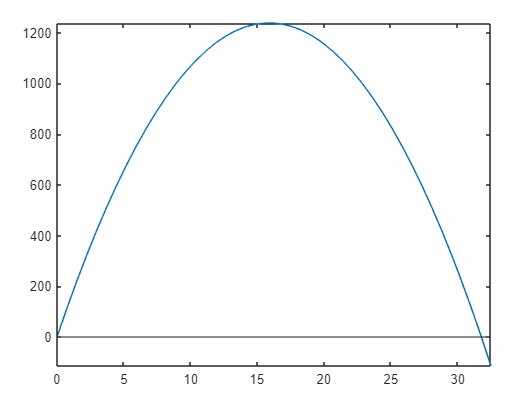

Grafen viser at vores $y_{maks}$ ligger lidt over 1200.

Herfra kan vi omskrive vores læren om energi, så vi kan finde punktet på kurven, hvor projektilet "mister" sin energi:

- 
$$y_{maks} = 1238.53 m$$


clear all
% Graf til funktioner af noget:
g = 9.81;
y_0 = 0;
theta = 60;
v_y = 180 * sin(deg2rad(theta));
y = @(t) y_0 + v_y.*t-0.5*g*t.^2;

%fplot(y,[0 32.5]) 
%hold on
%xline(0)
%yline(0)
%hold off

clear all;
syms t;
% massen:
m = 1;

% Tyngdeaccelerationen:
g = 9.81;

% Start højden:
y_0 = 0;

% Affyringsvinklen:
theta = 60;

% Hastigheden:
v_0 = 180;

% Hastigheden i y-retningen:
v_y = v_0 * sin(deg2rad(theta));

% Tiden til y_maks:
y_top = vpa(solve(v_y - g*t,t),6);

% y_maks
y_maks = vpa((0.5*m*v_y^2)/(m*g),6)

$$y\_maks = 1238.53$$

### ***Underopgave 1.B:****Forskriften y(x) for projektilets banekurve, i det viste koordinatsystem. y(x) og den skrå rampe ønskes plottet i samme koordinatsystem* 

Forskriften for rampen kan findes som:

- 
$$y_1(x) = tan(20\degree ) \cdot x$$


For at finde forskriften for vores projektil, så skal vi finde et udtryk for x-retningen af tiden:

- 
$$v_x = v_0 \cdot cos(60\degree )$$


- Afstanden $x = v_x \cdot t \rightarrow t = \frac{x}{v_x}$

Den fundne beskrivelse indsætter vi vores sted formel for y.

- 
$$v_y = v_0 \cdot sin(60\degree )$$


- 
$$y = v_y \cdot t - 0.5 \cdot g \cdot t^2$$


Da vores $t = \frac{x}{v_x}$, så erstatter vi t og får:

- 
$$y = v_y \cdot \frac{x}{v_x} - 0.5 \cdot g \cdot \frac{x}{v_x}^2$$


Hvortil vores funktions udtryk for y bliver:

- 
$$y(x) = 1.73205 \cdot x - 0.000605556 \cdot x^2$$


clear all;
% Graf til funktioner af noget:
syms t;
g = 9.81;
y_0 = 0;
theta = 60;

% Hastigheden y:
v_y = 180 * sin(deg2rad(theta));

% Distancen for y:
z = y_0 + v_y.*t-0.5*g*t.^2;

% Tiden til nul for y:
tiden_til_nul = vpa(solve(z,t),6);
% x-akse afstanden for tiden y.
Afstanden_til_nul = 180 * cosd(60) * 31.7807;

y =@(p) 1.73205.*p - 0.000605556*p.^2;
f =@(p) tand(20).*p;
hold on
fplot(y,[0 Afstanden_til_nul])
fplot(f,[0 Afstanden_til_nul])

### ***Underopgave 1.C: Afstand R***

Til denne opgave kan vi solve for tiden mellem dem:

clear all;
syms t;
y =1.73205*t - 0.000605556*t^2;
f =tand(20)*t;

R = vpa(solve(y == f,t),6)

$$tiden = \left(\begin{array}{c} 0\\ 2259.21 \end{array}\right)$$

# Opgave 2:

Informationer:

- Pendulets vinkel: $\theta = 0\degree $

- Pendulets vinkelhastighed: $\omega = 4 \frac{rad}{s}$

- Massen af pendulet: $m = 100 kg$

- Pendulets gyrationsradius: $k_G = 250 mm \rightarrow 0.25 m$

- Tyngdeaccelerationen: $g = 9.81 \frac{m}{s^2}$

- Afstanden til hængsel fra tyngdepunkt:$r = 0.75 m$

### ***Underopgave 2.A: ****Pendulets masseinertimoment om pendulets tyngdepunkt, *$I_G$ 

Da vi kender til pendulets gyrationsradius, så kan vi finde $I_G$ som:

- 
$$I_G = k_G^2 * m = 6.25 \, kg\cdot m^2$$


clear all
k_G = 0.25;
m = 100;

I_G = k_G^2*m;

### ***Underopgave 2.B: ****Pendulets masseinertimoment om pendulets ende, *$I_C$ 

 Da vi kender masseinertimomentet for tyngdepunktet, så kan vi finde $I_C$ som:

- 
$$I_C = I_G + r^2 * m = 62.5 \, kg \cdot m^2$$


r = 0.75;
I_C = I_G + r^2 * m;

# *Opgave 3:*

Informationer:

- massen = 1 kg

- K_1 = 10 N/m

- K_2 = 6 N/m

- K_3 = 10 N/m

- g = 9.81 m/s^2

Før vi starter opgaven skal den samlede fjederkostant findes:

- K_12 = $\frac{k_1 \cdot k_2}{k_1 + k_2} = 3.75$

- K_123 $= K_{12} + K_3 = 13.75$

K1 = 10;
K2 = 6;
K3 = 10;

K12 = (K1*K2)/(K1+K2);
K123 = K12 + K3;

### ***Underopgave 3.A: ****Den cykliske egenfrekvens ω1 *

Egenfrekvensen er angivet som:

- 
$$\omega_n = \sqrt{\frac{k}{m}} = \sqrt{\frac{k_{123}}{m}} = 3.7081 \frac{Rad}{sec}$$


En Rad/sec = 9.5492965964254 omdr./min

- 
$$\omega_n = 35.41 \frac{omdr.}{min}$$
 

clear all;
k = 13.75;
m = 1;

omega_n = sqrt(k/m);

omega_n =        3.7081


omdr = 9.5492965964254;
omega_omdr = omega_n * omdr;

omega_omdr =         35.41
